.clearvars
clc
addpath(genpath('D:\OneDrive\MATLAB_FILES\UsefulFunctions'))

# Installation Errors from manGyro to secondaryGyro two axis Gimbals (outer Pitch, inner Yaw)

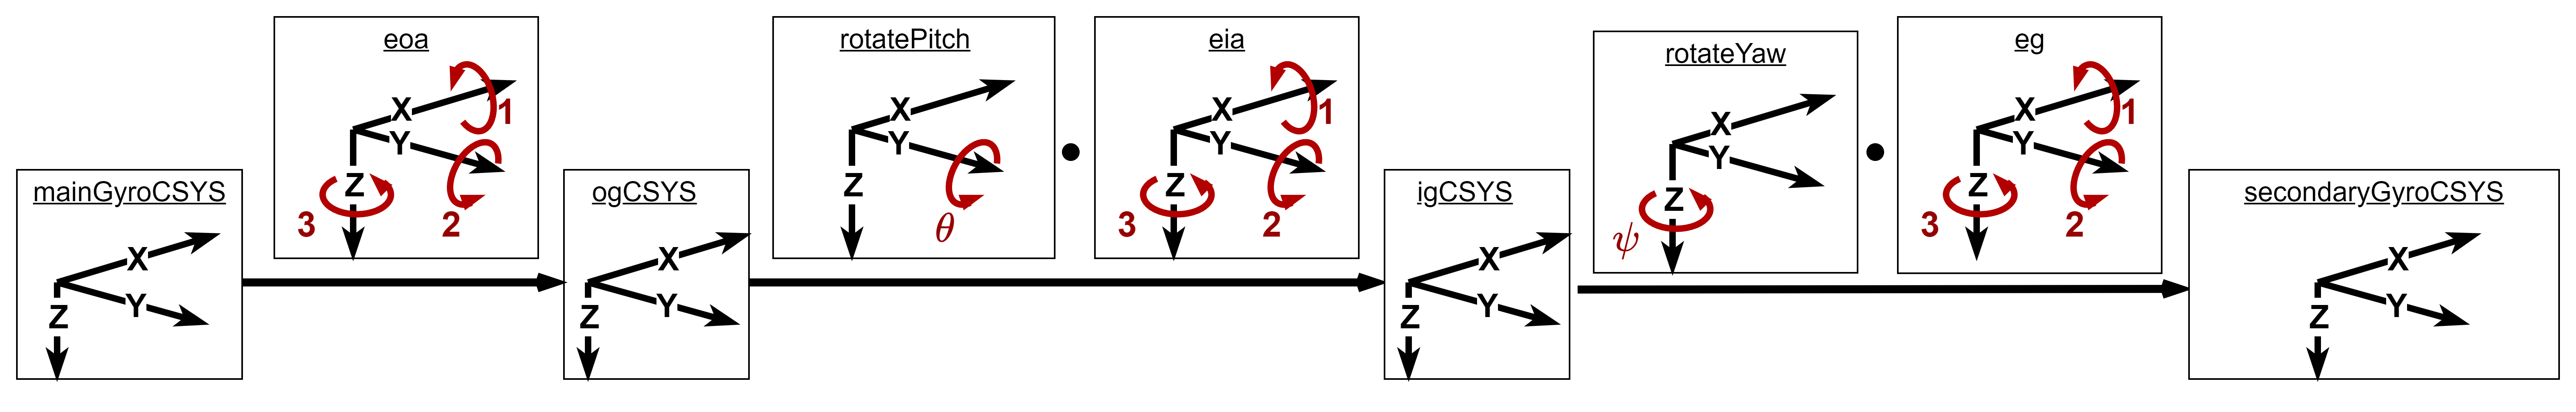


$$\text{\underline{Kinematic equations:}} \\
\omega_b - \text{Imu measurment} \\
\theta, \psi,  \dot \theta, \dot \psi - \text{encoders measurments} \\
E - \text{unknown DCM matrix, small errors rotations} \\
R - \text{measured DCM matrix, big rotations} \\

\text{\underline{Assumptions:}} \\
\text{Orthogonality errors of gyro and Imu axes are negligible}$$



$$\omega_{b}^{gCS} = E_{iaCS}^{gCS}\cdot \underbrace{\left\{ \left[ \matrix {0 \cr 0 \cr \dot \psi} \right] + R_{\psi} \cdot E_{oaCS}^{iaCS} \cdot \underbrace {\left\{ \left[ \matrix {0 \cr \dot \theta \cr 0} \right] + R_{\theta} \cdot E_{bCS}^{oaCS}\cdot \omega_{b}^{bCS} \right\}}_{\omega_{b}^{ogCS}} \right\}}_{\omega_{b}^{igCS}}$$


syms eoa1 eoa2 eoa3 theta theta_o eia1 eia2 eia3 psi psi_o eg1 eg2 eg3 c_theta s_theta c_psi s_psi real
syms psi_dot theta_dot wgX wgY wgZ wbX P Q R real

wg = [wgX;wgY;wgZ];
wb = [P;Q;R];

## Reducing un-observable error terms, by choosing a "correct" rotation order of *E* matrices


$$\text{Expansion of kinemtics, when relative velocities vectos omitted for clarity} \\
\omega_b^{gCS} = \underbrace{R_Y(eg_2) \cdot R_X(eg_1) \cdot R_Z (eg_3)}_{eg}
\cdot R_{\psi}(\psi+\psi_o)\cdot 
\underbrace{R_z(eia_3) \cdot R_X(eia_1) \cdot R_Y(eia_2)}_{eia}
\cdot R_{\theta}(\theta+\theta_o) \cdot
\underbrace{R_Y(eoa_2) \cdot R_X(eoa_1) \cdot R_Z(eoa_3)}_{eoa}
\cdot \omega_b^{bCS}$$



$$\text{Above kinematics, can be rewrited as follows, without lost of information} \\
\omega_b^{gCS} = \underbrace{R_Y(eg_2) \cdot R_X(eg_1)}_{\tilde{eg}}
\cdot R_{\psi}(\psi+\tilde \psi_o)\cdot 
\underbrace{R_X(eia_1)}_{\tilde {eia}}
\cdot R_{\theta}(\theta+\tilde \theta_o) \cdot
\underbrace{R_X(eoa_1) \cdot R_Z(eoa_3)}_{\tilde {eoa}}
\cdot \omega_b^{bCS}$$


eoa_ = rotateX(eoa1)*rotateZ(eoa3);
eoa = subs( eoa_, {cos(eoa1), sin(eoa1), cos(eoa3), sin(eoa3)},{1, eoa1, 1, eoa3});

eia_ = rotateX(eia1);
eia = subs( eia_, {cos(eia1), sin(eia1)}, {1, eia1});

eg_ = rotateY(eg2)*rotateX(eg1);
eg = subs( eg_, {cos(eg2), sin(eg2), cos(eg1), sin(eg1)}, {1, eg2, 1, eg1});

rog_ = rotateY(theta+theta_o);
rog = subs( expand( rog_ ), {cos(theta), sin(theta), cos(theta_o), sin(theta_o)}, {c_theta, s_theta, 1, theta_o});

rig_ = rotateZ(psi+psi_o);
rig = subs( expand( rig_ ), {cos(psi), sin(psi), cos(psi_o), sin(psi_o)}, {c_psi, s_psi, 1, psi_o});

### Vector of unknown and observable errors

X = [ symvar(eoa) symvar(eia) symvar(eg) theta_o psi_o]';

## Converting Kinematic equation to matrix form


$$A_{lin} \cdot X = w_g + \tilde b_{lin} = b$$


wg_c = simplify (expand ( eg*( [0;0;psi_dot]+rig*eia*( [0;theta_dot;0]+rog*eoa*wb ))))


A = subs( jacobian(wg_c, X), X, 0*X )

$$A = \left[\begin{array}{ccccccc} R\,s_{\psi }+Q\,c_{\psi }\,s_{\theta } & Q\,c_{\psi }\,c_{\theta }-P\,s_{\psi } & R\,c_{\theta }\,s_{\psi }+P\,s_{\psi }\,s_{\theta } & 0 & -\dot{\psi }-R\,c_{\theta }-P\,s_{\theta } & -R\,c_{\psi }\,c_{\theta }-P\,c_{\psi }\,s_{\theta } & Q\,c_{\psi }+c_{\psi }\,\dot{\theta }-P\,c_{\theta }\,s_{\psi }+R\,s_{\psi }\,s_{\theta }\\ R\,c_{\psi }-Q\,s_{\psi }\,s_{\theta } & -P\,c_{\psi }-Q\,c_{\theta }\,s_{\psi } & R\,c_{\psi }\,c_{\theta }+P\,c_{\psi }\,s_{\theta } & \dot{\psi }+R\,c_{\theta }+P\,s_{\theta } & 0 & R\,c_{\theta }\,s_{\psi }+P\,s_{\psi }\,s_{\theta } & R\,c_{\psi }\,s_{\theta }-s_{\psi }\,\dot{\theta }-P\,c_{\psi }\,c_{\theta }-Q\,s_{\psi }\\ -Q\,c_{\theta } & Q\,s_{\theta } & -Q-\dot{\theta } & P\,c_{\theta }\,s_{\psi }-c_{\psi }\,\dot{\theta }-Q\,c_{\psi }-R\,s_{\psi }\,s_{\theta } & Q\,s_{\psi }+s_{\psi }\,\dot{\theta }+P\,c_{\psi }\,c_{\theta }-R\,c_{\psi }\,s_{\theta } & P\,c_{\theta }-R\,s_{\theta } & 0 \end{array}\right]$$


b_lin_ = (-1)*subs(wg_c, X, 0*X);
b = wg + b_lin_

$$b = \left[\begin{array}{c} \mathrm{wgX}-Q\,s_{\psi }-s_{\psi }\,\dot{\theta }-P\,c_{\psi }\,c_{\theta }+R\,c_{\psi }\,s_{\theta }\\ \mathrm{wgY}-Q\,c_{\psi }-c_{\psi }\,\dot{\theta }+P\,c_{\theta }\,s_{\psi }-R\,s_{\psi }\,s_{\theta }\\ \mathrm{wgZ}-\dot{\psi }-R\,c_{\theta }-P\,s_{\theta } \end{array}\right]$$

## Least Square Approximation of Unknown Error Terms

For each test, matrix A and b, can be calculated

### 
$$\text{Test 1 - P motion only; \quad \dot \theta, \dot \psi, \theta, \psi  =0}$$


A1_ = subs(A, {Q, R, theta_dot, psi_dot, c_theta, s_theta, c_psi, s_psi}, {0, 0, 0, 0, 1, 0, 1, 0});
b1_ = subs(b, {Q, R, theta_dot, psi_dot, c_theta, s_theta, c_psi, s_psi}, {0, 0, 0, 0, 1, 0, 1, 0});

A1 = A1_(2:end, :);
b1 = b1_(2:end, :);

A1*X == b1

$$ans = \left[\begin{array}{c} -P\,{\mathrm{eoa}}_{3}-P\,\psi_{o}=\mathrm{wgY}\\ P\,{\mathrm{eg}}_{2}+P\,\theta_{o}=\mathrm{wgZ} \end{array}\right]$$

### 
$$\text{Test 2 - Q motion only; \quad \dot \theta, \dot \psi, \theta, \psi  =0}$$


A2_ = subs(A, {P, R, theta_dot, psi_dot, c_theta, s_theta, c_psi, s_psi}, {0, 0, 0, 0, 1, 0, 1, 0});
b2_ = subs(b, {P, R, theta_dot, psi_dot, c_theta, s_theta, c_psi, s_psi}, {0, 0, 0, 0, 1, 0, 1, 0});

A2 = A2_([1;3], :);
b2 = b2_([1;3], :);

A2*X == b2

$$ans = \left[\begin{array}{c} Q\,{\mathrm{eoa}}_{3}+Q\,\psi_{o}=\mathrm{wgX}\\ -Q\,{\mathrm{eg}}_{1}-Q\,{\mathrm{eia}}_{1}-Q\,{\mathrm{eoa}}_{1}=\mathrm{wgZ} \end{array}\right]$$

### 
$$\text{Test 3 - R motion only; \quad \dot \theta, \dot \psi, \theta, \psi  =0}$$


A3_ = subs(A, {P, Q, theta_dot, psi_dot, c_theta, s_theta, c_psi, s_psi}, {0, 0, 0, 0, 1, 0, 1, 0});
b3_ = subs(b, {P, Q, theta_dot, psi_dot, c_theta, s_theta, c_psi, s_psi}, {0, 0, 0, 0, 1, 0, 1, 0});

A3 = A3_(1:end-1, :);
b3 = b3_(1:end-1, :);

A3*X == b3

$$ans = \left[\begin{array}{c} -R\,{\mathrm{eg}}_{2}-R\,\theta_{o}=\mathrm{wgX}\\ R\,{\mathrm{eg}}_{1}+R\,{\mathrm{eia}}_{1}+R\,{\mathrm{eoa}}_{1}=\mathrm{wgY} \end{array}\right]$$

### 
$$\text{Test 4 - \dot \theta \,motion only; \dot \psi, \psi, P, Q, R  =0}$$


A4_ = subs(A, {P, Q, R, psi_dot, c_psi, s_psi}, {0, 0, 0, 0, 1, 0});
b4_ = subs(b, {P, Q, R, psi_dot, c_psi, s_psi}, {0, 0, 0, 0, 1, 0});

A4 = A4_([1;3], :);
b4 = b4_([1;3], :);

A4*X == b4

$$ans = \left[\begin{array}{c} \psi_{o}\,\dot{\theta }=\mathrm{wgX}\\ -{\mathrm{eg}}_{1}\,\dot{\theta }-{\mathrm{eia}}_{1}\,\dot{\theta }=\mathrm{wgZ} \end{array}\right]$$

### 
$$\text{Test 5 - \dot \psi\,motion only; \dot \theta, \theta, P, Q, R  =0}$$


A5_ = subs(A, {P, Q, R, theta_dot, c_theta, s_theta}, {0, 0, 0, 0, 1, 0});
b5_ = subs(b, {P, Q, R, theta_dot, c_theta, s_theta}, {0, 0, 0, 0, 1, 0});

A5 = A5_(1:end-1, :);
b5 = b5_(1:end-1, :);

A5*X == b5

$$ans = \left[\begin{array}{c} -{\mathrm{eg}}_{2}\,\dot{\psi }=\mathrm{wgX}\\ {\mathrm{eg}}_{1}\,\dot{\psi }=\mathrm{wgY} \end{array}\right]$$

## Checking for redundant information

A_full = [A1;A2;A3;A4;A5]

$$A\_full = \left[\begin{array}{ccccccc} 0 & -P & 0 & 0 & 0 & 0 & -P\\ 0 & 0 & 0 & 0 & P & P & 0\\ 0 & Q & 0 & 0 & 0 & 0 & Q\\ -Q & 0 & -Q & -Q & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -R & -R & 0\\ R & 0 & R & R & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \dot{\theta }\\ 0 & 0 & -\dot{\theta } & -\dot{\theta } & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -\dot{\psi } & 0 & 0\\ 0 & 0 & 0 & \dot{\psi } & 0 & 0 & 0 \end{array}\right]$$

rank(A_full) == size(A_full,1)

ans = logical
   0


matrix A_full is rank difficient, therefore linear depended rows are exists:

- row 1 and row 3, are scale of each other (-1 eq.)

- row 2 and row 5, same story (-1 eq.)  --> line 2 of Test 1 - P motion - A1(2,:), can be reduced (row 2 )

- row 4 and row 6, same story (-1 eq.) --> since F.T has P, and R motions,  Test 2 - Q motion -  A2, can be reduced (rows 3 and 4)

A_obs = [A1(1,:);A3;A4;A5]

$$A\_obs = \left[\begin{array}{ccccccc} 0 & -P & 0 & 0 & 0 & 0 & -P\\ 0 & 0 & 0 & 0 & -R & -R & 0\\ R & 0 & R & R & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \dot{\theta }\\ 0 & 0 & -\dot{\theta } & -\dot{\theta } & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -\dot{\psi } & 0 & 0\\ 0 & 0 & 0 & \dot{\psi } & 0 & 0 & 0 \end{array}\right]$$

b_obs = [b1(1,:);b3;b4;b5]

$$b\_obs = \left[\begin{array}{c} \mathrm{wgY}\\ \mathrm{wgX}\\ \mathrm{wgY}\\ \mathrm{wgX}\\ \mathrm{wgZ}\\ \mathrm{wgX}\\ \mathrm{wgY} \end{array}\right]$$

rank(A_obs) == size(A_obs,1)

ans = logical
   1


X

$$X = \left[\begin{array}{c} {\mathrm{eoa}}_{1}\\ {\mathrm{eoa}}_{3}\\ {\mathrm{eia}}_{1}\\ {\mathrm{eg}}_{1}\\ {\mathrm{eg}}_{2}\\ \theta_{o}\\ \psi_{o} \end{array}\right]$$

## Generate Functions

generateFunctions = 0;

switch generateFunctions

    case 1

        A1_func = matlabFunction(A1(1,:), 'file', 'A1_func');
        A3_func = matlabFunction(A3, 'file', 'A3_func');
        A4_func = matlabFunction(A4, 'file', 'A4_func');
        A5_func = matlabFunction(A5, 'file', 'A5_func');

        b1_func = matlabFunction(b1(1,:), 'file', 'b1_func');
        b3_func = matlabFunction(b3, 'file', 'b3_func');
        b4_func = matlabFunction(b4, 'file', 'b4_func');
        b5_func = matlabFunction(b5, 'file', 'b5_func');

    case 0
        disp('No Function Generated')
end

No Function Generated


## 
$$\text{Inverse Kinematics} \quad \omega_{Hor},\omega_{Ver} \to  \dot \theta, \dot \psi$$



$$\text{Non Linear IK Equations:} \\
\left[ \matrix{
\dot \theta \cr
\dot \psi
} \right] = f(P,Q,R, \omega_{gY}, \omega_{gZ}, \theta, \psi, all \, error \,terms) $$


eq_FK = simplify(expand(A*X==b));
eq_IK = solve(eq_FK(2:3), {theta_dot, psi_dot});


$$\text{Linear IK Equations:} \\
\left[ \matrix{
\dot \theta \cr
\dot \psi
} \right] = [A_{IK reduced}]\cdot 
\left[
\matrix{
P \cr Q \cr R \cr \omega_{gY} \cr \omega_{gZ} 
}
\right]$$


reducing order of small errors product:

eq_IK_reduced = subs(jacobian([eq_IK.theta_dot;eq_IK.psi_dot], X), X, X*0)*X + subs([eq_IK.theta_dot;eq_IK.psi_dot], X, X*0);

Y = [P, Q, R, wgY, wgZ];

A_IK_reduced_ = equationsToMatrix(eq_IK_reduced, Y);
A_IK_reduced = subs(collect(simplify(collect(subs(A_IK_reduced_, {c_theta, s_theta, c_psi, s_psi}, {cos(theta), sin(theta), cos(psi), sin(psi)}), X)), X),...
    {cos(theta), sin(theta), cos(psi), sin(psi)},  {c_theta, s_theta, c_psi, s_psi});

size(A_IK_reduced)

ans =      2     5


switch generateFunctions
    case 1
        matlabFunction(A_IK_reduced, 'file', 'A_IK.m')

    case 0
        disp('No Function Generated')
end

No Function Generated



disp(A_IK_reduced)

$$\left[\begin{array}{ccccc} {\mathrm{eoa}}_{3}-{\mathrm{eia}}_{1}\,s_{\theta }+\frac{c_{\theta }\,\psi_{o}}{{c_{\psi }}^{2}}+\frac{c_{\theta }\,s_{\psi }}{c_{\psi }}-\frac{s_{\psi }\,s_{\theta }\,\theta_{o}}{c_{\psi }} & \frac{c_{\theta }\,{\mathrm{eoa}}_{3}\,s_{\psi }}{c_{\psi }}+\frac{{\mathrm{eoa}}_{1}\,s_{\psi }\,s_{\theta }}{c_{\psi }}-1 & -{\mathrm{eoa}}_{1}-c_{\theta }\,{\mathrm{eia}}_{1}-\frac{\psi_{o}\,s_{\theta }}{{c_{\psi }}^{2}}-\frac{s_{\psi }\,s_{\theta }}{c_{\psi }}-\frac{c_{\theta }\,s_{\psi }\,\theta_{o}}{c_{\psi }} & \frac{1}{c_{\psi }}+\frac{\psi_{o}\,s_{\psi }}{{c_{\psi }}^{2}} & -\frac{{\mathrm{eg}}_{1}}{c_{\psi }}\\ \frac{c_{\theta }\,{\mathrm{eia}}_{1}\,s_{\psi }}{c_{\psi }}-c_{\theta }\,\theta_{o}-\frac{c_{\theta }\,{\mathrm{eg}}_{2}}{c_{\psi }}-s_{\theta } & c_{\theta }\,{\mathrm{eoa}}_{1}-{\mathrm{eoa}}_{3}\,s_{\theta } & s_{\theta }\,\theta_{o}-c_{\theta }+\frac{{\mathrm{eg}}_{2}\,s_{\theta }}{c_{\psi }}-\frac{{\mathrm{eia}}_{1}\,s_{\psi }\,s_{\theta }}{c_{\psi }} & {\mathrm{eg}}_{1}+\frac{{\mathrm{eia}}_{1}}{c_{\psi }}-\frac{{\mathrm{eg}}_{2}\,s_{\psi }}{c_{\psi }} & 1 \end{array}\right]$$

disp(Y')

$$\left[\begin{array}{c} P\\ Q\\ R\\ \mathrm{wgY}\\ \mathrm{wgZ} \end{array}\right]$$